# **Taller N° 11: Modelo epidemiológico SIRV**

## **Juan Pimienta Durán                                                    ID Epik: 1000258360**

# **Introducción**

El objetivo de este taller es resolver numéricamente, por el método numérico de Runge-Kutta implementado en la función ode45 de MATLAB, la ecuación de estado de un modelo epidemiológico SIRV (SIR con vacunados) no lineal en un archivo Live Script de MATLAB y analizar el resultado.

#### Modelo matemático

Supuestos: 

#### -- población cerrada (no llegan personas de otros lugares) y constante (*s* + *i* + *r* + *v* = 1)

#### -- población uniforme, mezcla homogénea (sin consideraciones de edad, distribución espacial, educación o estructura social).

Donde:

#### *-- s* es el porcentaje de personas susceptibles (pueden contraer la enfermedad)

#### *-- i* es el porcentaje de personas infectadas

#### *-- r* es el porcentaje de personas recuperadas (y que no vuelven a contraer la enfermedad, es decir, quedan inmunes)

#### *-- v* es el porcentaje de personas vacunadas.

#### -- β es la tasa de transmisión

#### -- γ es la tasa de recuperación y aislamiento

#### -- δ es la tasa de vacunación.

***R0 es el número reproductivo básico.***

***Caso para estudiar (hay epidemia, R0 > 1): β = 0.1, γ = 0.02, δ = 0.001, s(0) = 0.8, i(0) = 0.1, r(0) = 0, v(0) = 0.1***

# **Punto 1: **

Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones. ¿Cuál es el efecto de la vacunación? ¿Qué porcentaje mínimo de la población debe estar vacunada para que el pico de infectados se incremente sólo en un 50% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.15)?

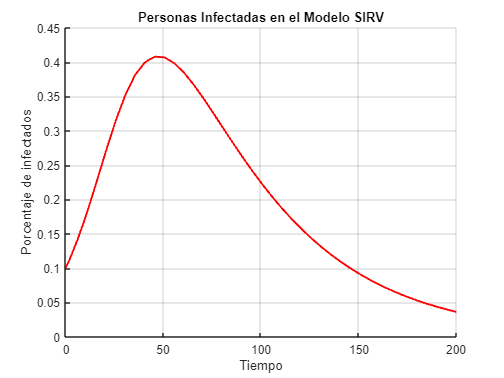

% Parámetros del modelo
beta = 0.1;
gamma = 0.02;
delta = 0.001;

% Condiciones iniciales
s0 = 0.8;
i0 = 0.1;
r0 = 0;
v0 = 0.1;

% Vector de tiempos
tspan = [0 200]; % Intervalo de tiempo de simulación

% Resolución de la ecuación diferencial
[t, y] = ode45(@sirv_model, tspan, [s0, i0, r0, v0]);

% Extracción de las soluciones
s = y(:, 1);
k = y(:, 2);
r = y(:, 3);
v = y(:, 4);

% Graficar solo la solución de i(t)
figure
grid on
hold on
xlabel('Tiempo');
ylabel('Porcentaje de infectados');
title('Personas Infectadas en el Modelo SIRV');
plot(t, k, 'r', 'LineWidth', 1.5);
hold off

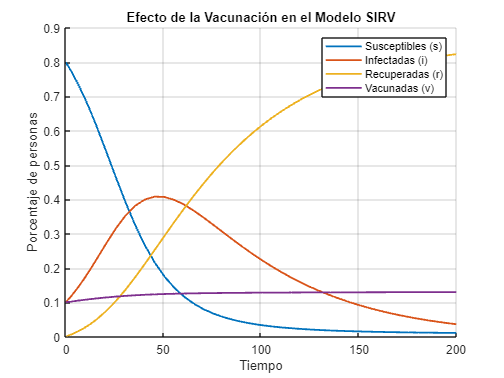

figure
grid on
hold on
plot(t, y, 'LineWidth', 1.5);
xlabel('Tiempo');
ylabel('Porcentaje de personas');
title('Efecto de la Vacunación en el Modelo SIRV');
legend('Susceptibles (s)', 'Infectadas (i)', 'Recuperadas (r)', 'Vacunadas (v)');
hold off

# Punto 2: 

Graficar sólo la solución *i*(*t*) con un aumento sólo de *i*(0) y usando al menos 5 valores. Observar que al cambiar *i*(0) cambia *s*(0), dado que la suma de todas las condiciones iniciales debe ser igual a 1. Interpretar los resultados.

% Valores iniciales de s, r y v
s00 = 0; % Se ajusta para que s + i + r + v sea igual a 1
r00 = 0;
v00 = 0;

% Valores iniciales de i(0) para variar
i0_values = [0.05, 0.1, 0.15, 0.2, 0.25];

% Preparar gráfico
figure;

    for j = 1:length(i0_values)
        i00 = i0_values(j);
        
        if i00 == 0.05
            s00 = 0.95
            % Resolución de la ecuación diferencial con valores iniciales modificados
            [t, y] = ode45(@sirv_model, tspan, [s00, i00, r00, v00]);
            a = s00+i00+r00+v00
        
            % Extracción de la solución de i(t)
            i = y(:, 2);
        end
           

        if i00 == 0.1
            s00= 0.9
            % Resolución de la ecuación diferencial con valores iniciales modificados
            [t, y] = ode45(@sirv_model, tspan, [s00, i00, r00, v00]);
        
            % Extracción de la solución de i(t)
            a = s00+i00+r00+v00
            i = y(:, 2);
          
        end

        if i00 == 0.15
            s00 = 0.85
            % Resolución de la ecuación diferencial con valores iniciales modificados
            [t, y] = ode45(@sirv_model, tspan, [s00, i00, r00, v00]);
            a = s00+i00+r00+v00
        
            % Extracción de la solución de i(t)
            i = y(:, 2);
        end

        if i00 == 0.2
            s00= 0.8
            % Resolución de la ecuación diferencial con valores iniciales modificados
            [t, y] = ode45(@sirv_model, tspan, [s00, i00, r00, v00]);
        
            % Extracción de la solución de i(t)
            a = s00+i00+r00+v00
            i = y(:, 2);
           
        end

        if i00 == 0.25
            s00 = 0.75
            % Resolución de la ecuación diferencial con valores iniciales modificados
            [t, y] = ode45(@sirv_model, tspan, [s00, i00, r00, v00]);
            a = s00+i00+r00+v00
        
            % Extracción de la solución de i(t)
            i = y(:, 2);
            
        end
        
        % Graficar la solución de i(t)
        plot(t, i, 'LineWidth', 1.5);
        hold on;
    end

s00 = 0.9500

a = 1

s00 = 0.9000

a = 1

s00 = 0.8500

a = 1

s00 = 0.8000

a = 1

s00 = 0.7500

a = 1

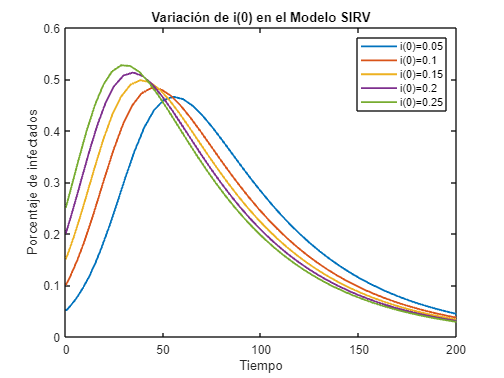

    

xlabel('Tiempo');
ylabel('Porcentaje de infectados');
title('Variación de i(0) en el Modelo SIRV');
 legend('i(0)=0.05', 'i(0)=0.1', 'i(0)=0.15', 'i(0)=0.2', 'i(0)=0.25');
 hold off

# Punto 3:

Graficar sólo la solución *i*(*t*) con un aumento sólo de β y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor máximo de beta (diferente de cero) se evitaría una epidemia? Interpretar los resultados.

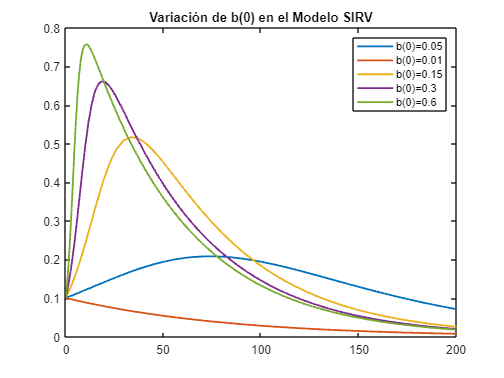

%beta_values = [0.05, 0.01, 0.15, 0.3, 0.6];
% Preparar gráfico
figure
  
% Resolución de la ecuación diferencial con valores iniciales modificados
[t, y] = ode45(@sirv_model_1, tspan, [s0, i0, r0, v0]);
% Extracción de la solución de i(t)
ia = y(:, 2);

% Graficar la solución de i(t)
plot(t, ia, 'LineWidth', 1.5);
hold on;
% Resolución de la ecuación diferencial con valores iniciales modificados
[t, y] = ode45(@sirv_model_2, tspan, [s0, i0, r0, v0]);
% Extracción de la solución de i(t)
ia = y(:, 2);

% Graficar la solución de i(t)
plot(t, ia, 'LineWidth', 1.5);
hold on;
% Resolución de la ecuación diferencial con valores iniciales modificados
[t, y] = ode45(@sirv_model_3, tspan, [s0, i0, r0, v0]);
% Extracción de la solución de i(t)
ia = y(:, 2);

% Graficar la solución de i(t)
plot(t, ia, 'LineWidth', 1.5);
hold on;
% Resolución de la ecuación diferencial con valores iniciales modificados
[t, y] = ode45(@sirv_model_4, tspan, [s0, i0, r0, v0]);
% Extracción de la solución de i(t)
ia = y(:, 2);

% Graficar la solución de i(t)
plot(t, ia, 'LineWidth', 1.5);
hold on;
% Resolución de la ecuación diferencial con valores iniciales modificados
[t, y] = ode45(@sirv_model_5, tspan, [s0, i0, r0, v0]);
            
% Extracción de la solución de i(t)
ia = y(:, 2);

% Graficar la solución de i(t)
plot(t, ia, 'LineWidth', 1.5);
hold on;
legend('b(0)=0.05', 'b(0)=0.01', 'b(0)=0.15', 'b(0)=0.3', 'b(0)=0.6');
title('Variación de b(0) en el Modelo SIRV');
hold off

# Punto 4:

Graficar sólo la solución *i*(*t*) con un aumento sólo de γ y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor mínimo de γ se evitaría una epidemia? Interpretar los resultados.

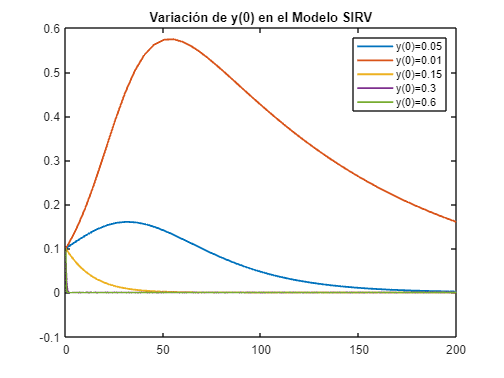

%gamma_values = [0.05, 0.01, 0.15, 0.3, 0.6];
% Preparar gráfico
figure
  
% Resolución de la ecuación diferencial con valores iniciales modificados
[t, y] = ode45(@sirv_model_6, tspan, [s0, i0, r0, v0]);
% Extracción de la solución de i(t)
ib = y(:, 2);

% Graficar la solución de i(t)
plot(t, ib, 'LineWidth', 1.5);
hold on;
% Resolución de la ecuación diferencial con valores iniciales modificados
[t, y] = ode45(@sirv_model_7, tspan, [s0, i0, r0, v0]);
% Extracción de la solución de i(t)
ib = y(:, 2);

% Graficar la solución de i(t)
plot(t, ib, 'LineWidth', 1.5);
hold on;
% Resolución de la ecuación diferencial con valores iniciales modificados
[t, y] = ode45(@sirv_model_8, tspan, [s0, i0, r0, v0]);
% Extracción de la solución de i(t)
ib = y(:, 2);

% Graficar la solución de i(t)
plot(t, ib, 'LineWidth', 1.5);
hold on;
% Resolución de la ecuación diferencial con valores iniciales modificados
[t, y] = ode45(@sirv_model_9, tspan, [s0, i0, r0, v0]);
% Extracción de la solución de i(t)
ib = y(:, 2);

% Graficar la solución de i(t)
plot(t, ib, 'LineWidth', 1.5);
hold on;
% Resolución de la ecuación diferencial con valores iniciales modificados
[t, y] = ode45(@sirv_model_10, tspan, [s0, i0, r0, v0]);
            
% Extracción de la solución de i(t)
ib = y(:, 2);

% Graficar la solución de i(t)
plot(t, ib, 'LineWidth', 1.5);
hold on;
legend('y(0)=0.05', 'y(0)=0.01', 'y(0)=0.15', 'y(0)=0.3', 'y(0)=0.6');
title('Variación de y(0) en el Modelo SIRV');
hold off

# Punto 5:

Graficar sólo la solución *i*(*t*) con un aumento sólo de δ y usando al menos 5 valores, uno de los cuales debe ser igual a cero. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con qué tasa mínima se debe vacunar la población de manera que el pico de infectados se incremente sólo en un 100% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.2)? Interpretar los resultados.

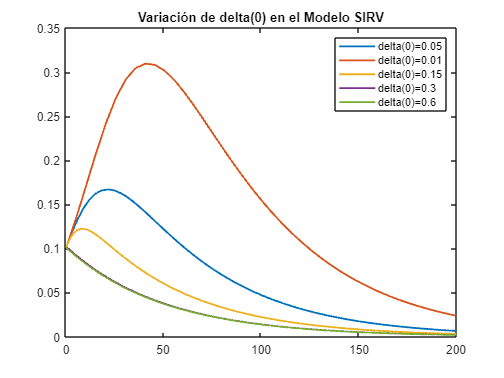

%delta_values = [0.05, 0.01, 0.15, 0.3, 0.6];
% Preparar gráfico
figure
  
% Resolución de la ecuación diferencial con valores iniciales modificados
[t, y] = ode45(@sirv_model_11, tspan, [s0, i0, r0, v0]);
% Extracción de la solución de i(t)
ic = y(:, 2);

% Graficar la solución de i(t)
plot(t, ic, 'LineWidth', 1.5);
hold on;
% Resolución de la ecuación diferencial con valores iniciales modificados
[t, y] = ode45(@sirv_model_12, tspan, [s0, i0, r0, v0]);
% Extracción de la solución de i(t)
ic = y(:, 2);

% Graficar la solución de i(t)
plot(t, ic, 'LineWidth', 1.5);
hold on;
% Resolución de la ecuación diferencial con valores iniciales modificados
[t, y] = ode45(@sirv_model_13, tspan, [s0, i0, r0, v0]);
% Extracción de la solución de i(t)
ic = y(:, 2);

% Graficar la solución de i(t)
plot(t, ic, 'LineWidth', 1.5);
hold on;
% Resolución de la ecuación diferencial con valores iniciales modificados
[t, y] = ode45(@sirv_model_14, tspan, [s0, i0, r0, v0]);
% Extracción de la solución de i(t)
ic = y(:, 2);

% Graficar la solución de i(t)
plot(t, ic, 'LineWidth', 1.5);
hold on;
% Resolución de la ecuación diferencial con valores iniciales modificados
[t, y] = ode45(@sirv_model_15, tspan, [s0, i0, r0, v0]);
            
% Extracción de la solución de i(t)
ic = y(:, 2);

% Graficar la solución de i(t)
plot(t, ic, 'LineWidth', 1.5);
hold on;
legend('delta(0)=0.05', 'delta(0)=0.01', 'delta(0)=0.15', 'delta(0)=0.3', 'delta(0)=0.6');
title('Variación de delta(0) en el Modelo SIRV');
hold off


% Función que define el modelo SIRV

    function dydt = sirv_model(t, y)
        beta = 0.1;
        gamma = 0.02;
        delta = 0.001;
        s = y(1);
        i = y(2);
        r = y(3);
        v = y(4);

        dydt = zeros(4, 1);
        dydt(1) = -beta * s * i - delta * s;
        dydt(2) = beta * s * i - gamma * i;
        dydt(3) = gamma * i;
        dydt(4) = delta * s;
    end

     function dydt = sirv_model_1(t, y)
        beta = 0.05;
        gamma = 0.02;
        delta = 0.001;
        s = y(1);
        i = y(2);
        r = y(3);
        v = y(4);

        dydt = zeros(4, 1);
        dydt(1) = -beta * s * i - delta * s;
        dydt(2) = beta * s * i - gamma * i;
        dydt(3) = gamma * i;
        dydt(4) = delta * s;
    end

 function dydt = sirv_model_2(t, y)
        beta = 0.01;
        gamma = 0.02;
        delta = 0.001;
        s = y(1);
        i = y(2);
        r = y(3);
        v = y(4);

        dydt = zeros(4, 1);
        dydt(1) = -beta * s * i - delta * s;
        dydt(2) = beta * s * i - gamma * i;
        dydt(3) = gamma * i;
        dydt(4) = delta * s;
 end
  function dydt = sirv_model_3(t, y)
        beta = 0.15;
        gamma = 0.02;
        delta = 0.001;
        s = y(1);
        i = y(2);
        r = y(3);
        v = y(4);

        dydt = zeros(4, 1);
        dydt(1) = -beta * s * i - delta * s;
        dydt(2) = beta * s * i - gamma * i;
        dydt(3) = gamma * i;
        dydt(4) = delta * s;
  end
   function dydt = sirv_model_4(t, y)
        beta = 0.3;
        gamma = 0.02;
        delta = 0.001;
        s = y(1);
        i = y(2);
        r = y(3);
        v = y(4);

        dydt = zeros(4, 1);
        dydt(1) = -beta * s * i - delta * s;
        dydt(2) = beta * s * i - gamma * i;
        dydt(3) = gamma * i;
        dydt(4) = delta * s;
   end
   function dydt = sirv_model_5(t, y)
        beta = 0.6;
        gamma = 0.02;
        delta = 0.001;
        s = y(1);
        i = y(2);
        r = y(3);
        v = y(4);

        dydt = zeros(4, 1);
        dydt(1) = -beta * s * i - delta * s;
        dydt(2) = beta * s * i - gamma * i;
        dydt(3) = gamma * i;
        dydt(4) = delta * s;
   end
  
   function dydt = sirv_model_6(t, y)
        beta = 0.1;
        gamma = 0.05;
        delta = 0.001;
        s = y(1);
        i = y(2);
        r = y(3);
        v = y(4);

        dydt = zeros(4, 1);
        dydt(1) = -beta * s * i - delta * s;
        dydt(2) = beta * s * i - gamma * i;
        dydt(3) = gamma * i;
        dydt(4) = delta * s;
   end
   function dydt = sirv_model_7(t, y)
        beta = 0.1;
        gamma = 0.01;
        delta = 0.001;
        s = y(1);
        i = y(2);
        r = y(3);
        v = y(4);

        dydt = zeros(4, 1);
        dydt(1) = -beta * s * i - delta * s;
        dydt(2) = beta * s * i - gamma * i;
        dydt(3) = gamma * i;
        dydt(4) = delta * s;
   end
   function dydt = sirv_model_8(t, y)
        beta = 0.1;
        gamma = 0.15;
        delta = 0.001;
        s = y(1);
        i = y(2);
        r = y(3);
        v = y(4);

        dydt = zeros(4, 1);
        dydt(1) = -beta * s * i - delta * s;
        dydt(2) = beta * s * i - gamma * i;
        dydt(3) = gamma * i;
        dydt(4) = delta * s;
   end
   function dydt = sirv_model_9(t, y)
        beta = 0.1;
        gamma = 3;
        delta = 0.001;
        s = y(1);
        i = y(2);
        r = y(3);
        v = y(4);

        dydt = zeros(4, 1);
        dydt(1) = -beta * s * i - delta * s;
        dydt(2) = beta * s * i - gamma * i;
        dydt(3) = gamma * i;
        dydt(4) = delta * s;
   end
   function dydt = sirv_model_10(t, y)
        beta = 0.1;
        gamma = 6;
        delta = 0.001;
        s = y(1);
        i = y(2);
        r = y(3);
        v = y(4);

        dydt = zeros(4, 1);
        dydt(1) = -beta * s * i - delta * s;
        dydt(2) = beta * s * i - gamma * i;
        dydt(3) = gamma * i;
        dydt(4) = delta * s;
    end
function dydt = sirv_model_11(t, y)
        beta = 0.1;
        gamma = 0.02;
        delta = 0.05;
        s = y(1);
        i = y(2);
        r = y(3);
        v = y(4);

        dydt = zeros(4, 1);
        dydt(1) = -beta * s * i - delta * s;
        dydt(2) = beta * s * i - gamma * i;
        dydt(3) = gamma * i;
        dydt(4) = delta * s;
end
function dydt = sirv_model_12(t, y)
        beta = 0.1;
        gamma = 0.02;
        delta = 0.01;
        s = y(1);
        i = y(2);
        r = y(3);
        v = y(4);

        dydt = zeros(4, 1);
        dydt(1) = -beta * s * i - delta * s;
        dydt(2) = beta * s * i - gamma * i;
        dydt(3) = gamma * i;
        dydt(4) = delta * s;
end
function dydt = sirv_model_13(t, y)
        beta = 0.1;
        gamma = 0.02;
        delta = 0.15;
        s = y(1);
        i = y(2);
        r = y(3);
        v = y(4);

        dydt = zeros(4, 1);
        dydt(1) = -beta * s * i - delta * s;
        dydt(2) = beta * s * i - gamma * i;
        dydt(3) = gamma * i;
        dydt(4) = delta * s;
end
function dydt = sirv_model_14(t, y)
        beta = 0.1;
        gamma = 0.02;
        delta = 3;
        s = y(1);
        i = y(2);
        r = y(3);
        v = y(4);

        dydt = zeros(4, 1);
        dydt(1) = -beta * s * i - delta * s;
        dydt(2) = beta * s * i - gamma * i;
        dydt(3) = gamma * i;
        dydt(4) = delta * s;
end
function dydt = sirv_model_15(t, y)
        beta = 0.1;
        gamma = 0.02;
        delta = 6;
        s = y(1);
        i = y(2);
        r = y(3);
        v = y(4);

        dydt = zeros(4, 1);
        dydt(1) = -beta * s * i - delta * s;
        dydt(2) = beta * s * i - gamma * i;
        dydt(3) = gamma * i;
        dydt(4) = delta * s;
end
